## 1. Extracting pseudorange data

% Read data.22o
fileID = fopen('data.22o', 'r');

% store every line
psedata = {}; 
line = fgetl(fileID);

% read data until 16th
for i = 1:15  % skip the first 15 lines
    line = fgetl(fileID); 
end

% extract data from 16th
while ischar(line)
    psedata{end+1} = line;  % add data
    line = fgetl(fileID);  % read next line
end

% close file
fclose(fileID);

% Initialize variables for satellite data
numColumns = length(psedata);  % total number of lines
pseudorangeData = {};  % Cell array to store data for each satellite
currentPseudorangeData = [];  % Temporary storage for current satellite data
pseudorangeCount = 0;  % satellite count

% Process the data lines
for i = 1:numColumns
    % Convert column to string and split by space
    lineStr = strtrim(psedata{i});  % remove spare space
    lineParts = strsplit(lineStr);  % split string by space
    [rows, cols] = size(lineParts);
    
    if cols > 5  % line contains satellite data (6th element is satellite code)
        % If there was previous satellite data, store it before moving to the next one
        if ~isempty(currentPseudorangeData)
            pseudorangeData{pseudorangeCount} = currentPseudorangeData;
        end
        
        % Start collecting data for the new satellite
        satelliteCode = lineParts{6};  % extract satellite code
        pseudorangeCount = pseudorangeCount + 1;  % increment satellite count
        currentPseudorangeData = NaN(12, 1);  % Initialize a column for the new satellite
    elseif cols <= 5  % line contains pseudorange data (1st element is pseudorange)
        pseudorange = str2double(lineParts{1});  % extract pseudorange value
        
        % Store pseudorange data in the current satellite's column
        if sum(~isnan(currentPseudorangeData)) < 12  % Only store if there is space (12 maximum)
            currentPseudorangeData(sum(~isnan(currentPseudorangeData)) + 1) = pseudorange;  % Store data
        end
    end
end

% Store the last satellite's data
if ~isempty(currentPseudorangeData)
    pseudorangeData{pseudorangeCount} = currentPseudorangeData;
end

% Create a new cell to store cleaned data
cleanData = cell(1, numel(pseudorangeData));

for i = 1:numel(pseudorangeData)
    currentData = pseudorangeData{i};

    % Remove NaN
    cleanData{i} = currentData(~isnan(currentData));
end

pseudorangeData = cleanData;

% Display the data
disp(pseudorangeData);

  Columns 1 through 1927

    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {12×1 double}    {

## 2.Extract satellite postions data

% Read satellite positions
satposdata = readmatrix('satpos.txt');

% Lines contain NaN
nanRows = any(isnan(satposdata), 2);

% Split the data using nanRows
satposData = {};
startIdx = 1;

% Using for loop to convert the matrix to the cell array
for i = 1:size(satposdata, 1)
    if nanRows(i)
        satposData{end+1} = satposdata(startIdx:i-1, :);
        startIdx = i+1;
    end
end

% Add final data 
if startIdx <= size(satposdata, 1)
    satposData{end+1} = satposdata(startIdx:end, :);
end

% Display the data
disp(satposData)

  Columns 1 through 1927

    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {12×5 double}    {

## 3.Combine two cell arraies below

% Combine the pesudorange data with the satpos data
finalData = cell(1, numel(satposData));

for i = 1:numel(satposData)
    finalData{i} = [satposData{i}, pseudorangeData{i}];
end

% Display the data
disp(finalData);

  Columns 1 through 1927

    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {12×6 double}    {

## 4.Position Determination using GPS Observations (Task 2)

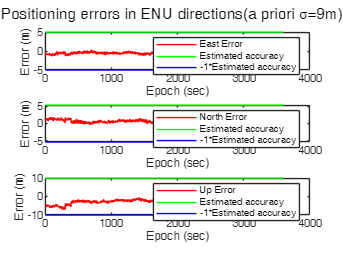

% 2.1 & 2.2
% Define the groundtruth
fid = fopen("true pos.txt", "r");
GroundTruth = textscan(fid, '%f %f %f');
GroundTruth = cell2mat(GroundTruth);
% disp(GroundTruth);

% 3600 second
num_seconds = 3600;
receiver_coords_ECEF = zeros(num_seconds, 4); % Estimate value per second
receiver_coords_ENU = zeros(num_seconds, 3); % Estimate value converted to ENU frame
Accuracymetric = zeros(num_seconds, 3); % Store estimated accuracy from covariance matrix
Accuracymetric_negative = zeros(num_seconds, 3);
DOP_values_ECEF = zeros(num_seconds, 6); % Store DOP values in ECEF frame
DOP_values_ENU = zeros(num_seconds, 5); % Store DOP values in ENU frame
satellite_counts = zeros(num_seconds, 1); % Store number of satellites per second

for t = 1:num_seconds
    % Extract satellite information per second
    satellites = finalData{t};
    num_satellites = size(satellites, 1);

    % Extract satellite position and pseudorange
    satellite_xyz = satellites(:, 2:4);
    correction = satellites(:, 5);
    pseudoranges = satellites(:, 6);

    % Initial estimates
    X = 0; Y = 0; Z = 0; cdt = 0;

    % Maximum number of iterations
    if t <= 1927
        max_iter = 12;
    else
        max_iter = 10;
    end

    % Convergence thresholds
    tol = 1e-6;

    for iter = 1:max_iter
        r = zeros(num_satellites, 1); % Residual
        J = zeros(num_satellites, 4); % Jacobian matrix
        for i = 1:num_satellites
            xi = satellite_xyz(i, 1);
            yi = satellite_xyz(i, 2);
            zi = satellite_xyz(i, 3);

            % Build pesudorange model
            rho = sqrt((X - xi)^2 + (Y - yi)^2 + (Z - zi)^2);
            r(i) = pseudoranges(i) - correction(i) - rho + cdt;

            % Calculate Jacobian matrix
            J(i, 1) = (X - xi) / rho;
            J(i, 2) = (Y - yi) / rho;
            J(i, 3) = (Z - zi) / rho;
            J(i, 4) = -1;
        end

        % Updating parameters
        delta_x = (J' * J) \ (J' * r);
        X = X + delta_x(1);
        Y = Y + delta_x(2);
        Z = Z + delta_x(3);
        cdt = cdt + delta_x(4);

        % Check iteration
        if norm(delta_x) < tol
            break;
        end
    end
    
    % Store estimation value
    receiver_coords_ECEF(t, :) = [X, Y, Z, cdt];

    % Convert ECEF frame to ENU frame
    phi = atan2(Z, sqrt(X^2 + Y^2));
    lambda = atan2(Y, X);

    % Built the transformation matrix
    R = [-sin(lambda), cos(lambda), 0, 0; -sin(phi)*cos(lambda), -sin(phi)*sin(lambda), cos(phi), 0; cos(phi)*cos(lambda), cos(phi)*sin(lambda), sin(phi), 0; 0, 0, 0, 1];

    % Compute errors
    error_ECEF(t, :) = [X - GroundTruth(1), Y - GroundTruth(2), Z - GroundTruth(3)];
    error_ENU(t, :) = R(1:3, 1:3) * error_ECEF(t, :)';

    % Built covariance matrix C, cofactor matrix Q and the standard
    % deviation of the pseudorange measurements sigma
    sigma =9;
    Q = inv(J' *J);
    C = (sigma^2) * Q;
    
    % Convert Q and C to ENU frame
    Q_ENU = R * Q * R';
    C_ENU = R * C * R';

    Accuracymetric(t, :) = [sqrt(C_ENU(1,1)), sqrt(C_ENU(2,2)), sqrt(C_ENU(3,3))];
    Accuracymetric_negative(t, :) = -Accuracymetric(t, :);

    % Compute DOP values in ECEF frame
    XDOP = sqrt(Q(1,1));
    YDOP = sqrt(Q(2,2));
    ZDOP = sqrt(Q(3,3));
    TDOP = sqrt(Q(4,4));
    GDOP = sqrt(XDOP^2 + YDOP^2 + ZDOP^2 + TDOP^2); % GDOP computation.
    PDOP = sqrt(XDOP^2 + YDOP^2 + ZDOP^2);  % PDOP computation
    DOP_values_ECEF(t, :) = [XDOP, YDOP, ZDOP, TDOP, PDOP, GDOP];
    
    % Compute DOP values in ECEF frame
    EDOP = sqrt(Q_ENU(1,1));
    NDOP = sqrt(Q_ENU(2,2));
    VDOP = sqrt(Q_ENU(3,3));
    HDOP = sqrt(NDOP^2 + EDOP^2);
    DOP_values_ENU(t, :) = [EDOP, NDOP, VDOP, TDOP, HDOP];

    % Store the number of satellites
    satellite_counts(t) = num_satellites;
end


% 2.3
figure;
subplot(3,1,1);
plot(1:num_seconds, error_ENU(:, 1), 'r', 'DisplayName', 'East Error');
hold on;
plot(1:num_seconds, mean(Accuracymetric(:, 1))*ones(size(1:num_seconds)), 'g', 'DisplayName', 'Estimated accuracy');
plot(1:num_seconds, mean(Accuracymetric_negative(:, 1))*ones(size(1:num_seconds)), 'b', 'DisplayName', '-1*Estimated accuracy');
legend('East Error', 'Estimated accuracy', '-1*Estimated accuracy');
xlabel('Epoch (sec)');
ylabel('Error (m)');

subplot(3,1,2);
plot(1:num_seconds, error_ENU(:, 2), 'r', 'DisplayName', 'North Error');
hold on;
plot(1:num_seconds, mean(Accuracymetric(:, 2))*ones(size(1:num_seconds)), 'g', 'DisplayName', 'Estimated accuracy');
plot(1:num_seconds, mean(Accuracymetric_negative(:, 2))*ones(size(1:num_seconds)), 'b', 'DisplayName', '-1*Estimated accuracy');
legend;
xlabel('Epoch (sec)');
ylabel('Error (m)');

subplot(3,1,3);
plot(1:num_seconds, error_ENU(:, 3), 'r', 'DisplayName', 'Up Error');
hold on;
plot(1:num_seconds, mean(Accuracymetric(:, 3))*ones(size(1:num_seconds)), 'g', 'DisplayName', 'Estimated accuracy');
plot(1:num_seconds, mean(Accuracymetric_negative(:, 3))*ones(size(1:num_seconds)), 'b', 'DisplayName', '-1*Estimated accuracy');
legend;
xlabel('Epoch (sec)');
ylabel('Error (m)');
name = sprintf('Positioning errors in ENU directions(a priori σ=%dm)', sigma);
sgtitle(name);

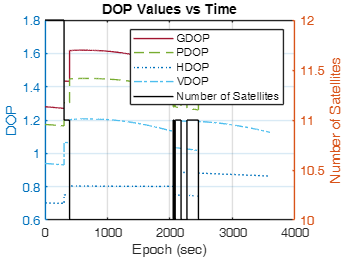


% 2.4
% Plot DOP values vs time
figure;
yyaxis left;
plot(1:num_seconds, DOP_values_ECEF(:,6), 'Color', '#A2142F', 'DisplayName', 'GDOP');
hold on;
plot(1:num_seconds, DOP_values_ECEF(:,5), 'Color', '#77AC30', 'DisplayName', 'PDOP');
plot(1:num_seconds, DOP_values_ENU(:,5), 'Color', '#0072BD', 'DisplayName', 'HDOP');
plot(1:num_seconds, DOP_values_ENU(:,3), 'Color', '#4DBEEE', 'DisplayName', 'VDOP');
ylabel('DOP');

yyaxis right;
plot(1:num_seconds, satellite_counts, 'k', 'DisplayName', 'Number of Satellites')
ylabel('Number of Satellites')

legend;
title('DOP Values vs Time');
xlabel('Epoch (sec)');

grid on;

## 5.Accuracy Assessment (Task 3)

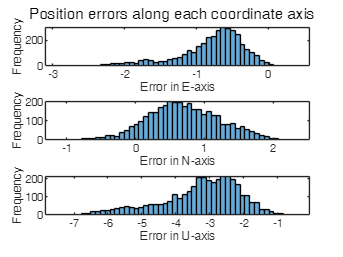

% Plot the histogram of the position errors along each coordinate axis
figure;
subplot(3,1,1);
histogram(error_ENU(:,1), 50);
xlabel('Error in E-axis');
ylabel('Frequency');

subplot(3,1,2);
histogram(error_ENU(:,2), 50);
xlabel('Error in N-axis');
ylabel('Frequency');

subplot(3,1,3);
histogram(error_ENU(:,3), 50);
xlabel('Error in U-axis');
ylabel('Frequency');

sgtitle('Position errors along each coordinate axis');


% Calculate maximum absolute error
max_absolute_error_east = max(vecnorm(error_ENU(:, 1), 2, 2));
max_absolute_error_north = max(vecnorm(error_ENU(:, 2), 2, 2));
max_absolute_error_up = max(vecnorm(error_ENU(:, 3), 2, 2));
disp(['Maximum Absolute Error in East: ', num2str(max_absolute_error_east)]);

Maximum Absolute Error in East: 2.8913


disp(['Maximum Absolute Error in North: ', num2str(max_absolute_error_north)]);

Maximum Absolute Error in North: 2.3423


disp(['Maximum Absolute Error in Vertical: ', num2str(max_absolute_error_up)]);

Maximum Absolute Error in Vertical: 7.4787



% Calculate mean error
mean_error_east = mean(error_ENU(:, 1));
mean_error_north = mean(error_ENU(:, 2));
mean_error_up = mean(error_ENU(:, 3));
disp(['Mean Error in East: ', num2str(mean_error_east)]);

Mean Error in East: -0.79195


disp(['Mean Error in North: ', num2str(mean_error_north)]);

Mean Error in North: 0.71002


disp(['Mean Error in Vertical: ', num2str(mean_error_up)]);

Mean Error in Vertical: -3.2811



% Calculate STD
std_deviation_east = std(error_ENU(:, 1));
std_deviation_north = std(error_ENU(:, 2));
std_deviation_up = std(error_ENU(:, 3));
disp(['Standard Deviation in East: ', num2str(std_deviation_east)]);

Standard Deviation in East: 0.46439


disp(['Standard Deviation in North: ', num2str(std_deviation_north)]);

Standard Deviation in North: 0.52856


disp(['Standard Deviation in Vertical: ', num2str(std_deviation_up)]);

Standard Deviation in Vertical: 1.1837



% Calculate RMS
rms_error_east = sqrt(mean(error_ENU(:, 1).^2));
rms_error_north = sqrt(mean(error_ENU(:, 2).^2));
rms_error_up = sqrt(mean(error_ENU(:, 3).^2));
disp(['RMS Error in East: ', num2str(rms_error_east)]);

RMS Error in East: 0.91803


disp(['RMS Error in North: ', num2str(rms_error_north)]);

RMS Error in North: 0.88511


disp(['RMS Error in Vertical: ', num2str(rms_error_up)]);

RMS Error in Vertical: 3.488



% Plot 
addpath('D:\MATLAB\radarChart\radarChart');
savepath;

figure;
subplot(2,2,1);
MAE = radarChart([max_absolute_error_east, max_absolute_error_north, max_absolute_error_up], '-o');

  @author : slandarer
  公众号  : slandarer随笔
  知乎    : slandarer

    Documentation for radarChart
    Folders named radarChart



MAE.PropName = {'East', 'North', 'Up'};
MAE.RLim = [0,8];
MAE = MAE.draw();
title('Maximum Absolute Error (m)');
MAE.setBkg('FaceColor',[0,0,.1]);
MAE.setPatchN(1, 'Color', [0.9290 0.6940 0.1250], 'MarkerFaceColor', [0.9290 0.6940 0.1250]);
MAE.setRLabel('FontSize',11,'FontName','Helvetica','Color',[0.9290 0.6940 0.1250]);

subplot(2,2,2);
ME = radarChart([mean_error_east, mean_error_north, mean_error_up], '-o');

  @author : slandarer
  公众号  : slandarer随笔
  知乎    : slandarer

    Documentation for radarChart
    Folders named radarChart



ME.RLim = [-5,1];
ME.PropName = {'East', 'North', 'Up'};
ME = ME.draw();
title('Mean Error (m)');
ME.setBkg('FaceColor',[0,0,.1]);
ME.setPatchN(1, 'Color', [0.9290 0.6940 0.1250], 'MarkerFaceColor', [0.9290 0.6940 0.1250]);
ME.setRLabel('FontSize',11,'FontName','Helvetica','Color',[0.9290 0.6940 0.1250]);

subplot(2,2,3);
STD = radarChart([std_deviation_east, std_deviation_north, std_deviation_up], '-o');

  @author : slandarer
  公众号  : slandarer随笔
  知乎    : slandarer

    Documentation for radarChart
    Folders named radarChart



STD.PropName = {'East', 'North', 'Up'};
STD.RLim = [0,2];
STD = STD.draw();
title('Standard Deviation (m)');
STD.setBkg('FaceColor',[0,0,.1]);
STD.setPatchN(1, 'Color', [0.9290 0.6940 0.1250], 'MarkerFaceColor', [0.9290 0.6940 0.1250]);
STD.setRLabel('FontSize',11,'FontName','Helvetica','Color',[0.9290 0.6940 0.1250]);

subplot(2,2,4);
RMS = radarChart([rms_error_east, rms_error_north, rms_error_up], '-o');

  @author : slandarer
  公众号  : slandarer随笔
  知乎    : slandarer

    Documentation for radarChart
    Folders named radarChart



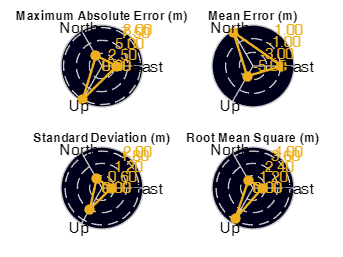

RMS.PropName = {'East', 'North', 'Up'};
RMS.RLim = [0,4];
RMS = RMS.draw();
title('Root Mean Square (m)');
RMS.setBkg('FaceColor',[0,0,.1]);
RMS.setPatchN(1, 'Color', [0.9290 0.6940 0.1250], 'MarkerFaceColor', [0.9290 0.6940 0.1250]);
RMS.setRLabel('FontSize',11,'FontName','Helvetica','Color',[0.9290 0.6940 0.1250]);